load gluco_data_master.mat

gluco_data_master_clean = rmmissing(gluco_data_master)

gluco_data_master_clean = 286×21 table
    glucose_level    mean_ch2    mean_ch3    max_ch2    max_ch3    std_ch2      std_ch3       var_ch2       var_ch3      crestf_ch2    crestf_ch3    kurtosis_ch2    kurtosis_ch3    skew_ch2     skew_ch3     rms_ch2    rms_ch3    moment_5_ch2    moment_5_ch3    moment_6_ch2    moment_6_ch3
    _____________    ________    ________    _______    _______    ________    __________    __________    __________    __________    _

gluco_data_master_clean = rmoutliers(gluco_data_master_clean, "percentiles", [1 95])

gluco_data_master_clean = 168×21 table
    glucose_level    mean_ch2    mean_ch3    max_ch2    max_ch3    std_ch2      std_ch3      var_ch2       var_ch3      crestf_ch2    crestf_ch3    kurtosis_ch2    kurtosis_ch3    skew_ch2    skew_ch3     rms_ch2    rms_ch3    moment_5_ch2    moment_5_ch3    moment_6_ch2    moment_6_ch3
    _____________    ________    ________    _______    _______    ________    _________    __________    __________    __________    ____

temp = gluco_data_master_clean.glucose_level

temp =     85
    95
   117
   100
    94
    95
    87
   123
    96
   107


gluco_data_master_norm = table2array(gluco_data_master_clean)

gluco_data_master_norm =    85.0000    0.5711    3.7688    0.6171    3.8502    0.0189    0.0257    0.0004    0.0007    0.9995    1.0000    2.2191    5.7853    0.1844    1.6999    0.5714    3.7688    0.0000    0.0000    0.0000    0.0000
   95.0000    0.3980    4.0724    0.4321    4.0960    0.0146    0.0516    0.0002    0.0027    0.9993    0.9999    2.7603   63.4925   -0.3989   -6.5796    0.3983    4.0727   -0.0000   -0.0002    0.0000    0.0001
  117.0000    0.4198    3.8332    0.4494    3.8645    0.0126    0.0110    0.0002    0.0001    0.9996    1.0000    2.6599    2.9333    0.0399    0.6662    0.4200    3.8332   -0.0000    0.0000    0.0000    0.0000
  100.0000    0.8395    3.8127    0.8764    4.0960    0.0170    0.2176    0.0003    0.0474    0.9998    0.9984    3.6465    1.4321   -0.7238    0.4549    0.8397    3.8189   -0.0000    0.0004    0.0000    0.0003
   94.0000    0.7410    3.7366    0.7834    4.0960    0.0201    0.1969    0.0004    0.0388    0.9996    0.9986    2.0235    2.0499 

gluco_data_master_norm = zscore(gluco_data_master_norm)

gluco_data_master_norm =    -1.0454   -0.3973    0.7856   -0.4256    0.6963   -0.5775   -0.3588   -0.5799   -0.3275    0.4765    0.3181   -0.4830   -0.0774    0.3047    1.3043   -0.3983    0.7826   -0.1129    0.0998   -0.4251   -0.1581
   -0.5910   -1.0997    1.3603   -1.1570    1.1306   -0.9645   -0.0423   -0.7863   -0.2549    0.3303    0.2700    0.4747    4.8817   -1.0450   -3.6573   -1.1010    1.3574   -0.1380    0.0937   -0.4325   -0.1564
    0.4085   -1.0114    0.9076   -1.0888    0.7215   -1.1463   -0.5385   -0.8651   -0.3470    0.5852    0.3342    0.2970   -0.3225   -0.0297    0.6849   -1.0129    0.9044   -0.1302    0.0998   -0.4348   -0.1581
   -0.3639    0.6919    0.8689    0.5994    1.1306   -0.7427    1.9867   -0.6744    1.3666    0.8656   -1.0333    2.0430   -0.4515   -1.7968    0.5582    0.6904    0.8773   -0.1774    0.1102   -0.4173   -0.1541
   -0.6365    0.2920    0.7248    0.2317    1.1306   -0.4617    1.7342   -0.5080    1.0559    0.6784   -0.8320   -0.8292   -0.3984 

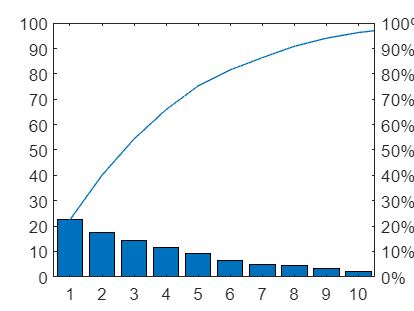

[coeff,score,latent,tsquared,explained,mu] = pca(gluco_data_master_norm);
pareto(explained,1)

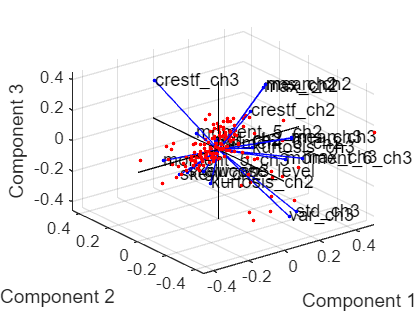

biplot(coeff(:,1:3),"Scores",score(:,1:3),"VarLabels",  {'glucose_level', ...
    'mean_ch2', 'mean_ch3', ...
    'max_ch2', 'max_ch3', ...
    'std_ch2', 'std_ch3', ...
    'var_ch2', 'var_ch3', ...
    'crestf_ch2', 'crestf_ch3', ...
    'kurtosis_ch2', 'kurtosis_ch3', ...
    'skew_ch2', 'skew_ch3', ...
    'rms_ch2', 'rms_ch3', ...
    'moment_5_ch2', 'moment_5_ch3', ...
    'moment_6_ch2', 'moment_6_ch3'});

close all
corrplot = corr(gluco_data_master_norm)

corrplot =     1.0000   -0.1502   -0.1376   -0.1486   -0.1033   -0.0549    0.0044   -0.0325    0.0522   -0.0410   -0.0867    0.1003   -0.0240    0.0706    0.0827   -0.1502   -0.1370   -0.0031    0.1033   -0.0208   -0.0135
   -0.1502    1.0000    0.1680    0.9959    0.1581    0.3833    0.0814    0.3401    0.0494    0.3606   -0.0332   -0.2697    0.0176   -0.2602   -0.1186    1.0000    0.1682    0.1214   -0.1878    0.2660    0.2012
   -0.1376    0.1680    1.0000    0.1602    0.9551    0.0104    0.1785    0.0043    0.1114    0.1373   -0.0609   -0.1516    0.0238   -0.1913   -0.0782    0.1679    1.0000   -0.0135   -0.1527    0.0140    0.1170
   -0.1486    0.9959    0.1602    1.0000    0.1552    0.4530    0.0899    0.4073    0.0609    0.3021   -0.0472   -0.2662    0.0065   -0.2134   -0.1011    0.9960    0.1605    0.1570   -0.1710    0.3240    0.1916
   -0.1033    0.1581    0.9551    0.1552    1.0000    0.0339    0.4304    0.0224    0.3636    0.1165   -0.3262   -0.0888    0.0274   -0.1664    0

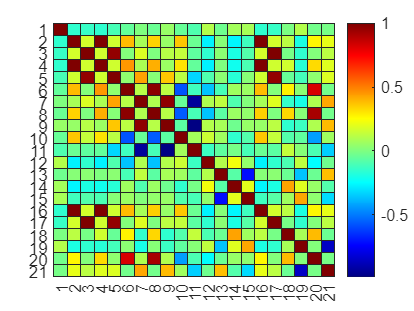

heatmp =   HeatmapChart with properties:

        XData: {21×1 cell}
        YData: {21×1 cell}
    ColorData: [21×21 double]

  Show all properties


heatmp = heatmap(corrplot,"Colormap", jet)

D = gluco_data_master_norm;
K = 10;
epochs = 500;
dist = squareform(pdist(gluco_data_master_norm));
alpha0 = 0.7;
lambda0 = 20;

P = cca(D,K, epochs, dist, [alpha0], [lambda0]);

iterating: 0 / 500 epochs
iterating: 1 / 500 epochs
iterating: 2 / 500 epochs
iterating: 3 / 500 epochs
iterating: 4 / 500 epochs
iterating: 5 / 500 epochs
iterating: 6 / 500 epochs
iterating: 7 / 500 epochs
iterating: 8 / 500 epochs
iterating: 9 / 500 epochs
iterating: 10 / 500 epochs
iterating: 11 / 500 epochs
iterating: 12 / 500 epochs
iterating: 13 / 500 epochs
iterating: 14 / 500 epochs
iterating: 15 / 500 epochs
iterating: 16 / 500 epochs
iterating: 17 / 500 epochs
iterating: 18 / 500 epochs
iterating: 19 / 500 epochs
iterating: 20 / 500 epochs
iterating: 21 / 500 epochs
iterating: 22 / 500 epochs
iterating: 23 / 500 epochs
iterating: 24 / 500 epochs
iterating: 25 / 500 epochs
iterating: 26 / 500 epochs
iterating: 27 / 500 epochs
iterating: 28 / 500 epochs
iterating: 29 / 500 epochs
iterating: 30 / 500 epochs
iterating: 31 / 500 epochs
iterating: 32 / 500 epochs
iterating: 33 / 500 epochs
iterating: 34 / 500 epochs
iterating: 35 / 500 epochs
iterating: 36 / 500 epochs
iterating: 

Pdist =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.6306         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

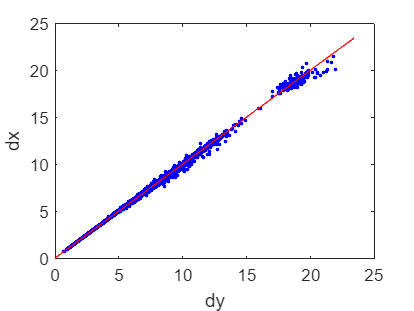

dydxplot(P, dist)

D = score(:,1:10);
K = 10;
epochs = 500;
dist = squareform(pdist(gluco_data_master_norm));
alpha0 = 0.7;
lambda0 = 20;

P = cca(D,K, epochs, [dist], [alpha0], [lambda0]);

iterating: 0 / 500 epochs
iterating: 1 / 500 epochs
iterating: 2 / 500 epochs
iterating: 3 / 500 epochs
iterating: 4 / 500 epochs
iterating: 5 / 500 epochs
iterating: 6 / 500 epochs
iterating: 7 / 500 epochs
iterating: 8 / 500 epochs
iterating: 9 / 500 epochs
iterating: 10 / 500 epochs
iterating: 11 / 500 epochs
iterating: 12 / 500 epochs
iterating: 13 / 500 epochs
iterating: 14 / 500 epochs
iterating: 15 / 500 epochs
iterating: 16 / 500 epochs
iterating: 17 / 500 epochs
iterating: 18 / 500 epochs
iterating: 19 / 500 epochs
iterating: 20 / 500 epochs
iterating: 21 / 500 epochs
iterating: 22 / 500 epochs
iterating: 23 / 500 epochs
iterating: 24 / 500 epochs
iterating: 25 / 500 epochs
iterating: 26 / 500 epochs
iterating: 27 / 500 epochs
iterating: 28 / 500 epochs
iterating: 29 / 500 epochs
iterating: 30 / 500 epochs
iterating: 31 / 500 epochs
iterating: 32 / 500 epochs
iterating: 33 / 500 epochs
iterating: 34 / 500 epochs
iterating: 35 / 500 epochs
iterating: 36 / 500 epochs
iterating: 

Pdist =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8260         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

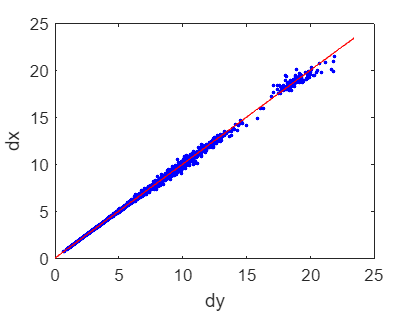

dydxplot(P, dist)

gluco_data_master_norm = array2table(gluco_data_master_norm, ...
    'VariableNames', {'glucose_level', ...
    'mean_ch2', 'mean_ch3', ...
    'max_ch2', 'max_ch3', ...
    'std_ch2', 'std_ch3', ...
    'var_ch2', 'var_ch3', ...
    'crestf_ch2', 'crestf_ch3', ...
    'kurtosis_ch2', 'kurtosis_ch3', ...
    'skew_ch2', 'skew_ch3', ...
    'rms_ch2', 'rms_ch3', ...
    'moment_5_ch2', 'moment_5_ch3', ...
    'moment_6_ch2', 'moment_6_ch3'});


gluco_data_master_norm.glucose_level = temp
%boxplot(gluco_data_master_norm.glucose_level)

close all
subplot(11,2,1), plot(gluco_data_master_norm.glucose_level, 'g');
subplot(11,2,3), plot(gluco_data_master_norm.mean_ch2, 'r');
subplot(11,2,4), plot(gluco_data_master_norm.mean_ch3, 'b');
subplot(11,2,5), plot(gluco_data_master_norm.max_ch2, 'r');
subplot(11,2,6), plot(gluco_data_master_norm.max_ch3, 'b');
subplot(11,2,7), plot(gluco_data_master_norm.std_ch2, 'r');
subplot(11,2,8), plot(gluco_data_master_norm.std_ch3, 'b');
subplot(11,2,9), plot(gluco_data_master_norm.var_ch2, 'r');
subplot(11,2,10), plot(gluco_data_master_norm.var_ch3, 'b');
subplot(11,2,11), plot(gluco_data_master_norm.crestf_ch2, 'r');
subplot(11,2,12), plot(gluco_data_master_norm.crestf_ch3, 'b');
subplot(11,2,13), plot(gluco_data_master_norm.kurtosis_ch2, 'r');
subplot(11,2,14), plot(gluco_data_master_norm.kurtosis_ch3, 'b');
subplot(11,2,15), plot(gluco_data_master_norm.skew_ch2, 'r');
subplot(11,2,16), plot(gluco_data_master_norm.skew_ch3, 'b')
subplot(11,2,17), plot(gluco_data_master_norm.rms_ch2, 'r')
subplot(11,2,18), plot(gluco_data_master_norm.rms_ch3, 'b')
subplot(11,2,19), plot(gluco_data_master_norm.moment_5_ch2, 'r')
subplot(11,2,20), plot(gluco_data_master_norm.moment_5_ch3, 'b')
subplot(11,2, 21), plot(gluco_data_master_norm.moment_6_ch2, 'r')
subplot(11,2,22), plot(gluco_data_master_norm.moment_6_ch3, 'b')
